load data\signal_1_wood_saw_decaying_pulse.mat

x=Basic_reading_Machine_1_Vibro_1(:,2)';

fs=Basic_reading_Machine_1_Vibro_1_metadata.SamplingRate;
dt=1/fs;

n=length(x);

t=(1:n).*dt;

Time Waveform (TW)    (high pass filter maye?)

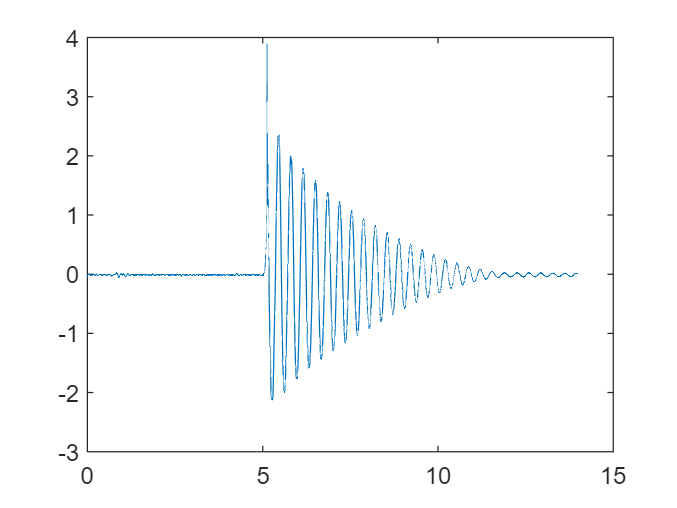

plot(t,x)


X=fft(x);
% X=ftt(x,2^19);
% n=2^19

mag=abs(X);
df=(fs/n)

df = 0.0714

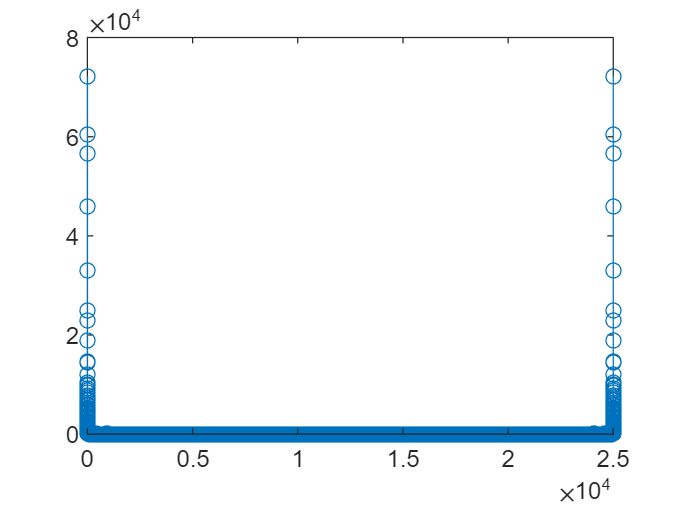

f=df*(0:n-1);
stem(f,mag')

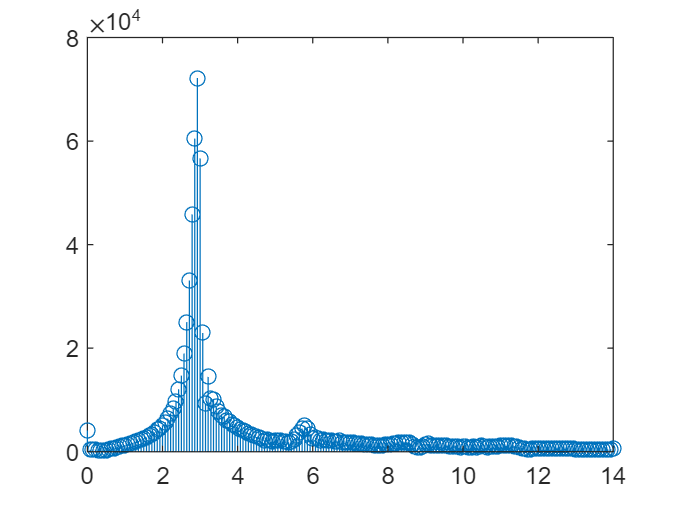


stem(f,mag')
xlim([0,14])

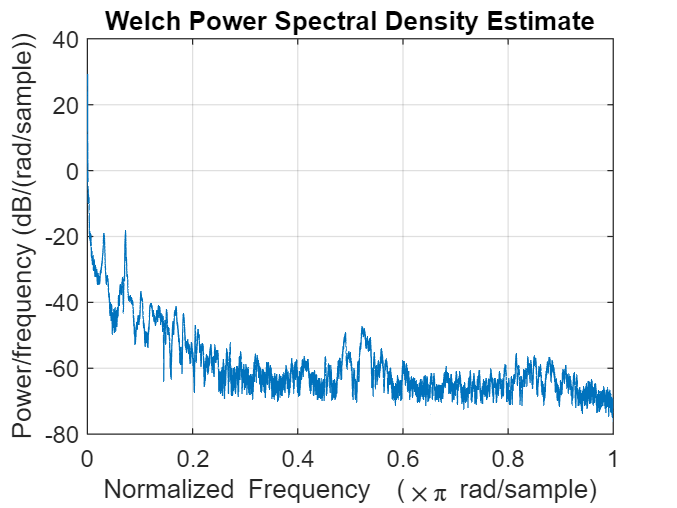

pwelch(x,fs)

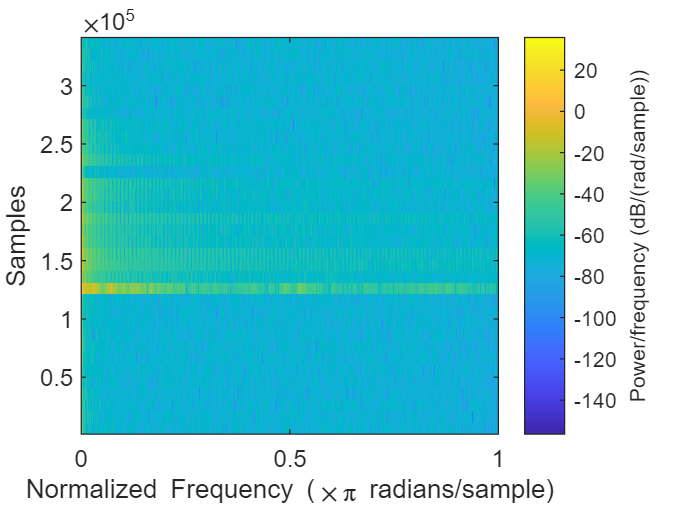

% spectrogram(x,fs)
spectrogram(x,0.5*fs,0.1*fs,2^19)